# CP241 Lab Assignment - 2

#### September 1, 2023

- `Submission via Teams`*: *`Assignments will be allocated to you via the Teams “``Assignments``” feature. You will have to upload your answer sheet via the same feature in Teams.`  `Answer sheets sent via e-mail will not be considered.`

- `File Logistics:` `Write only the code in .mlx (MATLAB Livescript) with name ”LA_2_<YOUR SERIAL NUMBER>” and submit in Teams. `

- `Note your ``serial number`` is ``last five digits`

- `Warning: ``Don't forget to ``turn in your assignment`` after you have attached your solution`

- `Warning: Attach only live scripts when submitting the assignments.`

`Due Data: 7`` September, 2023                                                                                                                                     ``Maximum Marks:` `20`

## `Question-1`

`Start with the cart pendulum model derived in class and simulate the motion for a time span of `$\left\lbrack \begin{array}{cc}
0 & 50
\end{array}\right\rbrack$` seconds, with initial condition: `$\mathit{\mathbf{x}}=0,\;\dot{\mathit{\mathbf{x}}} =0,\;\theta =\pi \;,\dot{\theta} =0$

`Take the following parameters:`

- `M = mass of the cart = 5 kg`

- `m = mass of the pendulum = 1 kg`

- `L = Length of the pendulum = 2 m`

- `b = friction coefficient = 10 `$\frac{N}{{\textrm{ms}}^{-1} }$

- `g = acceleration due to gravity = `$9\ldotp 8\;\frac{m}{s^2 }$

`Take the following piece-wise defined control input based on your ``serial no``. (For example if your serial no. is ``22319``):`


$$u(t) = 
\begin{cases}
-2\theta \text{ (1st digit)}, &0 \leq t < 10\\
-2\theta \text{ (2nd digit)}, &10 \leq t < 20\\
-3\theta \text{ (3rd digit)}, &20 \leq t < 30\\
-1\theta \text{ (4th digit)}, &30 \leq t < 40\\
-9\theta \text{ (last digit)}, &40 \leq t \leq 50\\
\end{cases}$$


`Use the ``ode45`` to solve the system ode for the above control input and answer the following questions`

- `Plot the conrtol input as a function of time.  [10 marks]`

- `Plot `$x\left(t\right)$` and `$\theta \left(t\right)$` as a function of time.        [10 marks]`

- `Simulate the motion of the system using the ``plotcartpend.m*`` function (No need to submit)`

`* can be downloaded from `[`https://github.com/FocasLab/CP-241-Applied-linear-and-non-linear-control.git`](https://github.com/FocasLab/CP-241-Applied-linear-and-non-linear-control.git) 

## Your main code starts from here

clear all; 
close all; 

%Parameter Initialization%
m = 1;      %Mass of the pendulum
M=5;        %Mass of the cart
L=2;        %Length of the pendulum
g=9.8;      %Gravitational acceleration
b=10;       %Friction Coeff.
tspan=[0,50];       %Time Span
x0 = [0;0;pi;0];    %Initial Conditions

%Solving the dynamics for states%
[t, states] = ode45( @(t,x) dynamics(m,M,L,b,g,x,t), tspan, x0);

%Finding the values of control input, as used in the dynamics%
for i = 1:length(states(:,1))
    u(i)=u_control(t(i),states(i,:));
end

### 1.  `Plot the conrtol input as a function of time.  [10 marks]`

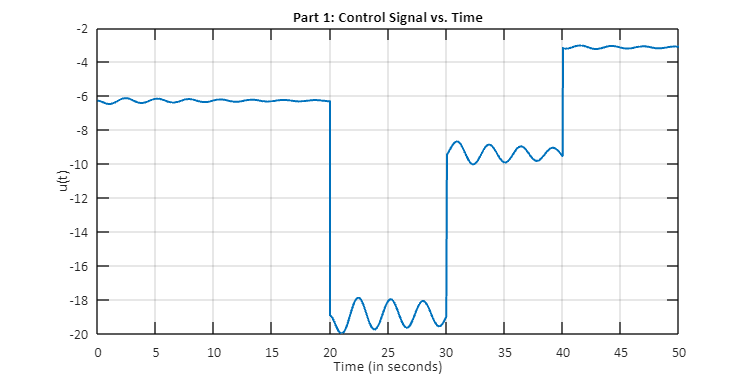

fig1 = figure();
plot(t,u, 'LineWidth', 2)
title('Part 1: Control Signal vs. Time');
xlabel('Time (in seconds)')
ylabel('u(t)');
grid on;
fig1.Position = [10,10,1000,500];
set(gca, 'FontName', 'Calibri', 'FontSize', 14);

### 2. `Plot the conrtol input as a function of time.  [10 marks]`

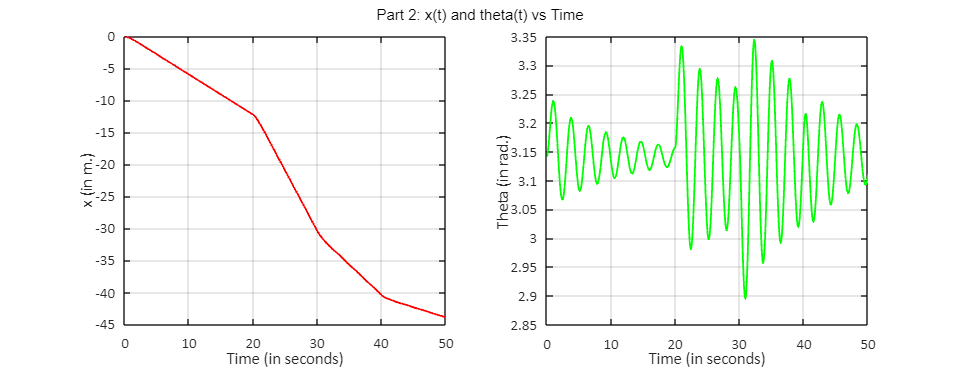

fig2 = figure();
subplot(1,2,1)
plot(t,states(:,1), 'r', 'LineWidth', 1.8);
xlabel('Time (in seconds)');
ylabel('x (in m.)');
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
grid on
subplot(1,2,2)
plot(t,states(:,3), 'g', 'LineWidth', 1.8);
xlabel('Time (in seconds)');
ylabel('Theta (in rad.) ');
sgtitle('Part 2: x(t) and theta(t) vs Time')
fig2.Position = [10,10,1300,500];
set(gca, 'FontName', 'Calibri', 'FontSize', 15);
grid on;

### 3. Motion Simulation [OPTIONAL]

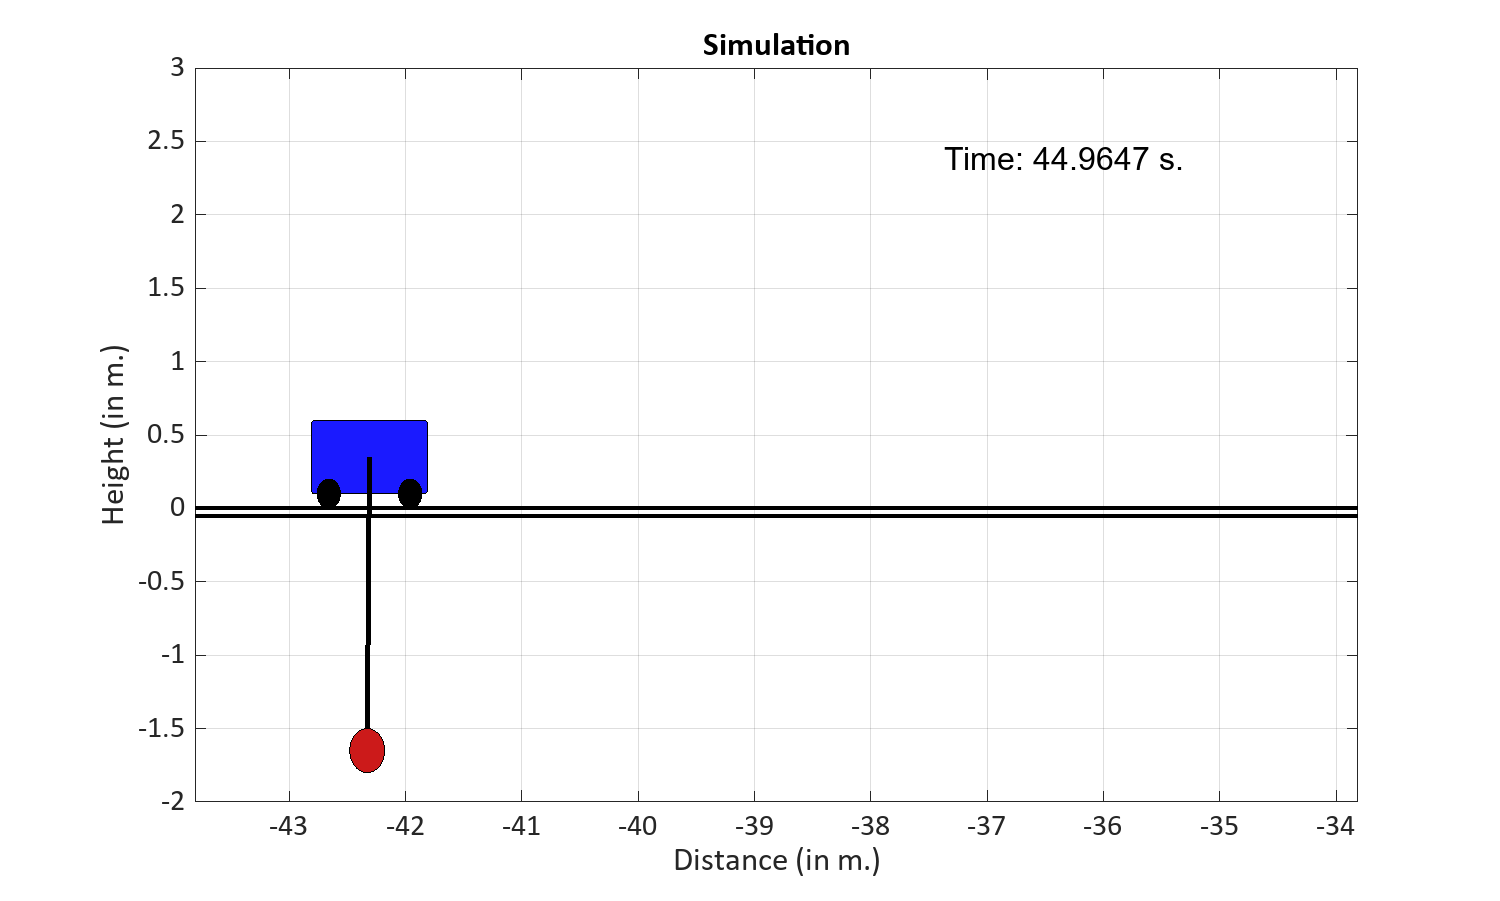

fig3 = figure();
for i = 1:length(states)
    plotcartpend(states(i,:), t(i));
end

### Function Declarations

function x_dot = dynamics(m_pendulum,M_cart,L,b,g,x,t)
    % System Dynamics
    Mbar  = M_cart + m_pendulum*(sin(x(3))^2);
    x_dot(1,1) = x(2);
    x_dot(2,1) = (m_pendulum*g*sin(x(3))*cos(x(3)) - m_pendulum*L*(x(4)^2)*sin(x(3))+u_control(t,x)-b*x(2))/Mbar;
    x_dot(3,1) = x(4);
    x_dot(4,1) = (cos(x(3))/L)*((m_pendulum*g*sin(x(3))*cos(x(3)) - m_pendulum*L*(x(4)^2)*sin(x(3)) + u_control(t,x) -b*x(2))/Mbar) + (g*sin(x(3))/L) ; 
end


function u = u_control(t,x)
    % Control Law
    % SR - 22631 
    if 0<=t && t<10
        u=-2*x(3);
    elseif 10<=t && t<20
        u=-2*x(3);
    elseif 20<=t && t<30
        u=-6*x(3);
    elseif 30<=t && t<40
        u=-3*x(3);
    elseif 40<=t && t<=50
        u=-1*x(3);
    else
        u=0;
    end
end


%%% [SLIGHTLY MODIFIED] Plotcartpend.m 
function plotcartpend(y,t)
    x = y(1);
    th = pi-y(3);
    
    % Cart params
    W = 1;  % cart width
    H = .5; % cart height
    wr = .2; % wheel radius
    cx = x; % cart horizontal position
    cy = wr/2+H/2; % cart vertical position
    
    
    % Ground
    plot([-10 + cx-1-W/2, 10+cx-1-W/2],[0 0],'k','LineWidth',2); hold on
    plot([-10+cx-W/2, 10+cx-W/2],[-0.05 -0.05],'k','LineWidth',2);
    
    %Cart
    rectangle('Position',[cx-W/2,cy-H/2,W,H],'Curvature',.1,'FaceColor',[0.1 0.1 1])
    
    % Wheel 1
    w1x = x-.9*W/2;
    w1y = 0;
    rectangle('Position',[w1x,w1y,wr,wr],'Curvature',1,'FaceColor','k')
    
    % Wheel 1
    w2x = x+.9*W/2-wr;
    w2y = 0;
    rectangle('Position',[w2x,w2y,wr,wr],'Curvature',1,'FaceColor','k')
    
    % Pendulum
    L = 2;  % pendulum length
    mr = 0.3; % Bob
    px = cx + L*sin(th);
    py = cy - L*cos(th);
    plot([x px],[cy py],'k','LineWidth',2.5)
    rectangle('Position',[px-mr/2,py-mr/2,mr,mr],'Curvature',1,'FaceColor',[0.8 0.1 0.1])
    
    %
    time = num2str(t);
    ylim([-2 3]);
    if (cx-W/2)<-4
        xlim([cx-1-W/2,cx+9-W/2]);
        text(cx+7.5-W/2, 2.5, append('Time: ',time, ' s.' ),'HorizontalAlignment','right','VerticalAlignment','top', 'FontSize', 16);
    else
        xlim([-5 5]);
        text(3.5, 2.5, append('Time: ',time, ' s.' ),'HorizontalAlignment','right','VerticalAlignment','top', 'FontSize', 16);
    end
    time = num2str(t);
    set(gcf,'Position',[100 550 1000 600])
    set(gca, 'FontName', 'Calibri','FontSize', 15)
    xlabel('Distance (in m.)');
    ylabel('Height (in m.)');
    title('Simulation')
    grid on;
    drawnow
    hold off
end